## **Esercitazione CasADi OCP - Moneta**

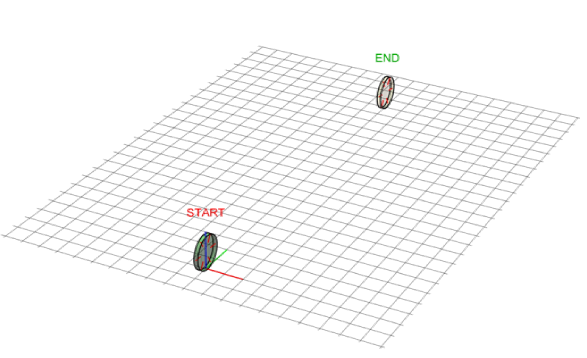$
\underset{X \in \mathbb{R}^{6}, \, U \in \mathbb{R}^{2}}{\text{minimize}} \,\,\,\,
J = \int_{0}^{T}(u_{1}^{2} +  u_{2}^{2})\,dt \\
\text{subject to} \,\,\,\,
 \dot{x}_1 = \rho x_6  \cos(x_3) \,\,t \in[0,T] \\
\,\,\,\,\,\,\,\,\,\,\,\,\,\,\,\,\,\,\,\,\,\,\, \dot{x}_2 = \rho x_6  \sin(x_3)\\
\,\,\,\,\,\,\,\,\,\,\,\,\,\,\,\,\,\,\,\,\,\,\, \dot{x}_3 = x_5 \\
\,\,\,\,\,\,\,\,\,\,\,\,\,\,\,\,\,\,\,\,\,\,\, \dot{x}_4 = x_6 \\
\,\,\,\,\,\,\,\,\,\,\,\,\,\,\,\,\,\,\,\,\,\,\, \dot{x}_5 = u_1/I_{\theta} \\
\,\,\,\,\,\,\,\,\,\,\,\,\,\,\,\,\,\,\,\,\,\,\, \dot{x}_6 = u_2/(I_{\phi} + m \rho^{2}) \\
\,\,\,\,\,\,\,\,\,\,\,\,\,\,\,\,\,\,\,\,\,\,\, x_6 \geq 0 \\
\,\,\,\,\,\,\,\,\,\,\,\,\,\,\,\,\,\,\,\,\,\,\, X(0) = [0, 0, \pi/2, 0, 0, 0]\\ 
\,\,\,\,\,\,\,\,\,\,\,\,\,\,\,\,\,\,\,\,\,\,\, x_1(T) = 0 \,\, x_2(T) = 10, \,\, x_3(T) = 3\pi/2 \\
X = [x_1, x_2, x_3, x_4, x_5, x_6] = [x, y, \theta, \phi, \dot{\theta}, \dot{\phi}]$

% Pulizia workspace
clear all
close all
clc

% comandi per cambiare la formattazione grafica delle scritte nei grafici
set(groot, 'defaultAxesTickLabelInterpreter','latex'); 
set(groot, 'defaultLegendInterpreter','latex');
set(groot, 'defaultTextInterpreter','latex');

%Import CasADi
addpath('../../../../Casadi/casadi-windows-matlabR2016a-v3.5.5')

import casadi.*
tol = 10^-5; %tollerance to avoid Nan

%Verifico funzionamento casadi
x = MX.sym('x');
jacobian(x^2,x)

ans = (2.*x)

## Dati e Griglia

% Dati del problema
rho = 0.45;             %raggio disco
m = 5;                  %massa disco
Itheta = 0.25*m*rho^2;  %Inerzia disco
Iphi = 0.5*m*rho^2;     %Inerzia disco

% Griglia di discretizzazione
T = 10;                  % Orizzonte temporale
N = 100;                 % Punti griglia
dt = T/N;                % Intervallo temporale
d = 2;                   % Grado polinomi

%Condizioni finali (t = T)(TASK)
xf = 0;                 
yf = 10;
theta_f = 3*pi/2;
theta_dot_f = 0;
phi_dot_f = 0;

## Definizione degli stati con sintassi CasADi

nx = 6; 
X = MX.sym('X', nx);

% x-coordinate
x       = X(1);             
x_lb    = -2*10;
x_ub    = 2*10;

% y-coordinate
y       = X(2);              
y_lb    = 0;
y_ub    = 2*yf;

% theta
theta       = X(3);              
theta_lb    = -2*pi;
theta_ub    = 2*pi;

% phi
phi       = X(4);              
phi_lb    = 0;
phi_ub    = 20*pi;

% tetha dot
theta_dot       = X(5);              
theta_dot_lb    = -pi/1;
theta_dot_ub    = pi/1;

% phi dot
phi_dot    = X(6);              
phi_dot_lb = 0;
phi_dot_ub = 4*pi/1;


% build vector of boundary and scaling factors
X_lb    = [x_lb; y_lb; theta_lb; phi_lb; theta_dot_lb; phi_dot_lb];
X_ub    = [x_ub; y_ub; theta_ub; phi_ub; theta_dot_ub; phi_dot_ub];

## Definizioni dei controlli con sintassi CasADi 

nu = 2;  
U = MX.sym('U', nu);

% Theta torque
tau_t      = U(1);         
tau_t_lb   = -2*Itheta;
tau_t_ub   =  2*Itheta;

% Phi torque
tau_p      = U(2);         
tau_p_lb   = -2*(Iphi + m*rho^2);
tau_p_ub   =  2*(Iphi + m*rho^2);

% build vectors of boundary and scaling factors
U_lb    = [tau_t_lb; tau_p_lb];
U_ub    = [tau_t_ub; tau_p_ub];

## Modello (sistema ODE)"

%ODE
dx = phi_dot*rho*cos(theta);
dy = phi_dot*rho*sin(theta);
dtheta = theta_dot;
dphi = phi_dot;
ddtheta = tau_t/Itheta;
ddphi = tau_p/(Iphi + m*rho^2);

node  = nx;
X_dot = [dx; dy; dtheta; dphi; ddtheta; ddphi];

## Funzione di costo

L = (tau_t)^2 + (tau_p)^2;

## Funzioni CasADi per costruire OCP

%Costruzione funzioni
F = Function('F', {X, U}, {X_dot}, {'X', 'U'}, {'X_dot'}); 
Q = Function('Q', {X, U}, {L}, {'X', 'U'}, {'L'});

%Valutazione
F([0,0,0,0,0,0],[1,0])

ans = [0, 0, 0, 0, 3.95062, 0]

## Condizioni Iniziali (t = 0)

% states
x_0 = 0;
y_0 = 0;
theta_0 = pi/2;
phi_0 = 0;
dtheta_0 = 0;
dphi_0 = 0;
X_0  = [x_0; y_0; theta_0; phi_0; dtheta_0; dphi_0];


## Costruzione NLP

% Start with an empty NLP
w    = {};                             
w0   = [];                          
lbw  = [];                         
ubw  = [];                          
J    = 0;
g    = {};                              
lbg  = [];                         
ubg  = [];   

% Initial conditions
X0  = MX.sym('X0', nx);         
w   = [w(:)', {X0}];
lbw = [lbw; X_0];
ubw = [ubw; X_0];
w0  = [w0; X_0];
Xk = X0;

% Coefficienti collocation
[D,C,B] = collocation(d);

% Loop to build NLP
for k = 1:N

    %Define previous variables
    if k == 1
        Xk_1 = Xk;
    else
        Xk_1 = Xk;
        Uk_1 = Uk;
    end
    
    % Initial guess
    if k == 1
        U_0 = [1; 0.1];
    else 
        X_0 = [0; k*yf/N; pi/2 + k*pi/N; k*(yf/rho)/N; pi/T; (yf/rho)/T];
        U_0 = [1; 0.1];
    end

    % Define k-th controls vector
    Uk = MX.sym(['U_' num2str(k)], nu);
    w   = [w(:)', {Uk}];
    lbw = [lbw; U_lb];
    ubw = [ubw; U_ub];
    w0  = [w0;  U_0];


    % State at collocation points
    Xkj = {};
    for j=1:d
        Xkj{j} = MX.sym(['X_' num2str(k) '_' num2str(j)], nx); %#ok<SAGROW>
        w   = [w(:)', Xkj(j)];
        lbw = [lbw; X_lb];
        ubw = [ubw; X_ub];
        w0  = [w0;  X_0];
    end

    Xk_end = D(1)*Xk;
    for j=1:d
       % Expression for the state derivative at the collocation point
       xp = C(1,j+1)*Xk;
       for r=1:d
           xp = xp + C(r+1,j+1)*Xkj{r};
       end

       % Append collocation equations
       fj  = F(Xkj{j}, Uk);
       qj  = Q(Xkj{j}, Uk);
       g   = [g(:)', {fj*dt - xp}];
       lbg = [lbg; zeros(nx,1)];
       ubg = [ubg; zeros(nx,1)];
       
       % Add contribution to the end state
       Xk_end = Xk_end + D(j+1)*Xkj{j};

       % Add contribution to quadrature formula
       J = J + B(j)*qj*dt;   
    end

    % Define (k+1)-th states vector
    Xk  = MX.sym(['X_' num2str(k+1)], nx);
    w   = [w(:)', {Xk}];
    lbw = [lbw; X_lb];
    ubw = [ubw; X_ub];
    w0  = [w0;  X_0];

    % Add equality constraint
    g = [g(:)', {Xk_end-Xk}];
    lbg = [lbg; zeros(nx,1)];
    ubg = [ubg; zeros(nx,1)];

end
    % Terminal constraint on x
    g = [g(:)', {Xk(1)-xf}];
    lbg = [lbg; zeros(1,1)];
    ubg = [ubg; zeros(1,1)];
    % Terminal constraint on y
    g = [g(:)', {Xk(2)-yf}];
    lbg = [lbg; zeros(1,1)];
    ubg = [ubg; zeros(1,1)];
    % Terminal constraint on teta
    g = [g(:)', {Xk(3)-theta_f}];
    lbg = [lbg; zeros(1,1)];
    ubg = [ubg; zeros(1,1)];
    % Terminal constraint on teta_dot
    g = [g(:)', {Xk(5)-theta_dot_f}];
    lbg = [lbg; zeros(1,1)];
    ubg = [ubg; zeros(1,1)];
    % Terminal constraint on psi_dot
    g = [g(:)', {Xk(6)-phi_dot_f}];
    lbg = [lbg; zeros(1,1)];
    ubg = [ubg; zeros(1,1)]; 
   

## Costruzione solver e soluzione

% Create an NLP solver 
prob = struct('f', J, 'x', vertcat(w{:}), 'g', vertcat(g{:}));
opts = struct;
opts.ipopt.linear_solver = 'ma57';
opts.ipopt.max_iter = 5000;
opts.ipopt.print_level = 5;
solver = nlpsol('solver', 'ipopt', prob, opts);

% Solve NLP
sol_sym = solver('x0', w0, 'lbx', lbw, 'ubx', ubw,'lbg', lbg, 'ubg', ubg);


******************************************************************************
This program contains Ipopt, a library for large-scale nonlinear optimization.
 Ipopt is released as open source code under the Eclipse Public License (EPL).
         For more information visit http://projects.coin-or.org/Ipopt
******************************************************************************

This is Ipopt version 3.12.3, running with linear solver ma57.

Number of nonzeros in equality constraint Jacobian...:     6393
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:      600

Total number of variables............................:     2000
                     variables with only lower bounds:        0
                variables with lower and upper bounds:     2000
                     variables with only upper bounds:        0
Total number of equality constraints.................:     1805
Total number of inequality constrai

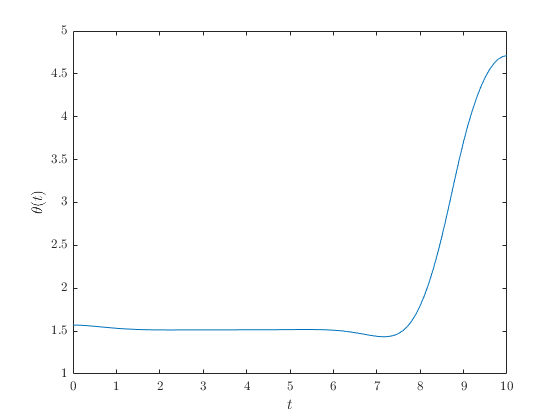


% Size of solution vector
siz    = length(sol_sym.x);

% Extract element from solution
x_opt      = full(sol_sym.x(1:(nx+nu+nx*d):siz));
y_opt      = full(sol_sym.x(2:(nx+nu+nx*d):siz));
theta_opt  = full(sol_sym.x(3:(nx+nu+nx*d):siz));
phi_opt    = full(sol_sym.x(4:(nx+nu+nx*d):siz));
dtheta_opt = full(sol_sym.x(5:(nx+nu+nx*d):siz));
dphi_opt   = full(sol_sym.x(6:(nx+nu+nx*d):siz));

tau_t_opt = full(sol_sym.x(7:(nx+nu+nx*d):siz));
tau_p_opt = full(sol_sym.x(8:(nx+nu+nx*d):siz));
time = [0; cumsum(dt*ones(N,1))];

% Postprocessing
figure(1)
plot(time, theta_opt)
xlabel('$t$')
ylabel('$\theta(t)$')

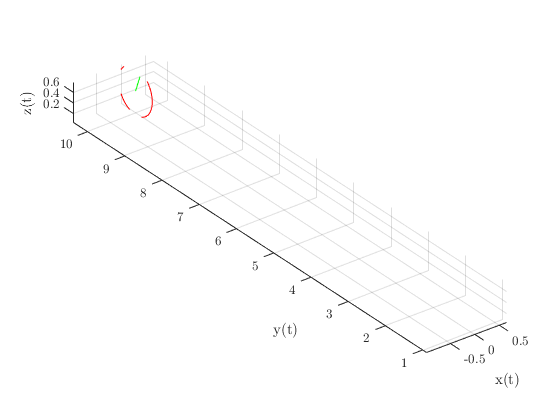


figure(2)
plot3(x_opt, y_opt, 0*x_opt)
grid on
axis('equal')
hold on
angle = linspace(0, 2*pi, N+1);
xd = rho*cos(angle);
yd = rho*sin(angle);
points = plot3(gca, nan, nan, nan, 'color', 'r','HandleVisibility','off');
pstar = plot3(gca, nan, nan, nan, 'color', 'g','HandleVisibility','off');
xlabel('x(t)')
ylabel('y(t)')
zlabel('z(t)')
for i = 1:N+1
    Rsg = [cos(theta_opt(i)-pi/2), -sin(theta_opt(i)-pi/2), 0; sin(theta_opt(i)-pi/2), cos(theta_opt(i)-pi/2), 0; 0, 0, 1];
    dg = [x_opt(i);y_opt(i);rho];
    gsg = [Rsg, dg; zeros(1,3), 1];
    data_new = gsg*[zeros(1, N+1); xd; yd; ones(1, N+1)];
    set(points, 'XData', data_new(1,:), 'YData', data_new(2,:), 'ZData', data_new(3,:));
    data_pstar_disk = [0; rho*cos(-phi_opt(i)); rho*sin(-phi_opt(i)); 1];
    data_pstar_disk_g = gsg*data_pstar_disk;
    data_pstar = [x_opt(i),data_pstar_disk_g(1);y_opt(i),data_pstar_disk_g(2);rho,data_pstar_disk_g(3)];
    set(pstar, 'XData', data_pstar(1,:), 'YData', data_pstar(2,:), 'ZData', data_pstar(3,:));
    xlim([-1 1])
    ylim([-0.5 11])
    zlim([0.000 0.900])
    drawnow
end